# Parametric Correlation Coefficients

## Question 1

They do look to be related in some positive fashion (positive slope between data sets) 

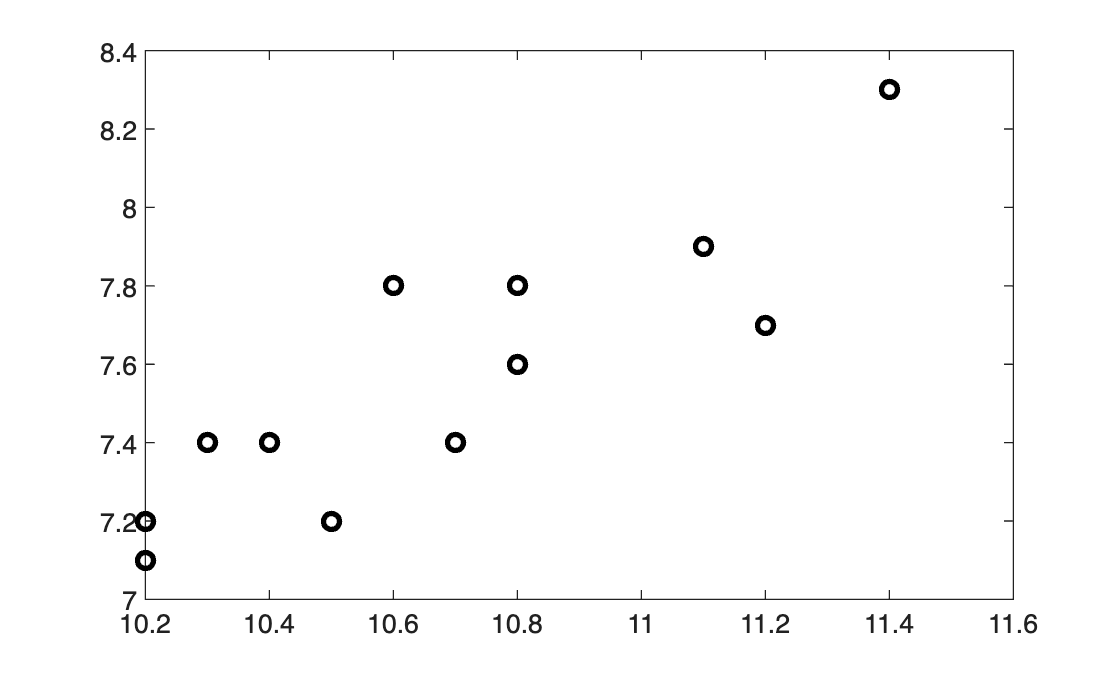

% Load and plot data
dataX = [10.4000   10.8000   11.1000   10.2000   10.3000   10.2000   10.7000   10.5000   10.8000   11.2000   10.6000   11.4000]';
dataY = [7.4000    7.6000    7.9000    7.2000    7.4000    7.1000    7.4000    7.2000    7.8000    7.7000    7.8000    8.3000]';
plot(dataX, dataY, 'ko', 'LineWidth',2)

## Question 2

The answers between the two approaches are the same

% Calculate the corrcoef by hand
n = length(dataX);
xBar = 1/n * sum(dataX);
yBar = 1/n * sum(dataY);

num = sum((dataX - xBar) .* (dataY - yBar)); 
denom = sqrt(sum((dataX-xBar).^2)) * sqrt(sum((dataY-yBar).^2));
r = num/denom;
fprintf('r value calculated by hand: %0.4f', r)

r value calculated by hand: 0.8704


% Calculate the corrcoef using the built-in function
r_Fxn = corrcoef(dataX, dataY);
fprintf('r value calculated by built-in function: %0.4f', r_Fxn(2))

r value calculated by built-in function: 0.8704

## Question 3

% Calculate the standared error and 95% CI
s_r = sqrt((1-r^2) / (n-2));
z_r = 0.5 * log((1+r) / (1-r));
s_z = sqrt((1) / (n-3));
confLevel = 0.95; 
zCrit = norminv((1-confLevel)/2); 
confInterval = [(z_r + zCrit * s_z) (z_r - zCrit * s_z)]; 
fprintf('Standard error: %0.4f', s_r)

Standard error: 0.1557

fprintf('95%% Confidence Interval: [%0.4f %0.4f]', confInterval(1), confInterval(2))

95% Confidence Interval: [0.6812 1.9879]

## Question 4

The value should be considered significant since the calculated test statistic t is of a greater magnitude than the calculated critical values. 

% Hypothesis Testing r = 0 
t = r/s_r;
alpha = 0.05; 
df = n-2; 
pLower = alpha/2; 
pUpper = 1-alpha/2;
tCrit = tinv([pLower, pUpper], df);

## Question 5

Yale's study is functionally the same as mine since the calculated lambda value is not large enough to reject the null of them being equal. Note: We used an approximate normal test here. 

% Hypothesis Testing r = r_s
rs = 0.75; 
s_rs = sqrt((1-rs^2) / (n-2));
z_rs = 0.5 * log((1+rs) / (1-rs));
lambda = (z_r - z_rs) / sqrt((1) / (n - 3));

## Question 6

% Power and sample size calculation 
target = 0.5; 
null = 0; 
power = sampsizepwr('t', [null s_r], target, [], n, 'Tail', 'right');
nout = sampsizepwr('t', [null s_r], target, power, [], 'Tail', 'right');

fprintf('Power: %0.4f', power);

Power: 1.0000

fprintf('Sample size: %0.4f', nout);

Sample size: 10.0000